# Using the Partial Differential Equation Toolbox

## Built-in solver: `pdepe`

MATLAB solves 1-D parabolic and elliptic partial differential equations of the form

$c\left(x,t,u,\frac{\partial u}{\partial x}\right)\frac{\partial u}{\partial t} = x^{-m}\frac{\partial}{\partial x}\left(x^mf\left(x,t,u,\frac{\partial u}{\partial x}\right)\right) + s\left(x,t,u,\frac{\partial u}{\partial x}\right)$,

using the command `pdepe`. Some 2-D or 3-D equations are sufficiently symmetric that they can also be written in this form. 

% m controls the symmetry of the problem
% m=0 is linear, m=1 is cylindrical, and m=2 is spherical
m = 0;
L = 1;
% Choose the resolution you need in space
xMesh = linspace(0,L,80);
% You can space time values closer or farther apart if you know
% something about the expected behavior of the system
smtSteps = linspace(0,0.03,121);
lrgtSteps = linspace(0.03,5,51);
tMesh = [smtSteps lrgtSteps(2:end)];

Define the necessary helper functions. You can write them anywhere you would like in a live script, including right here!

First, we should define the equation to solve. As an example, let's solve the heat equation where $\gamma$ is independent of $x$:

$\frac{\partial u}{\partial t} = \gamma \frac{\partial^2 u}{\partial x^2} $.

Note that this means $c=1, f = \gamma \frac{\partial u}{\partial x}$, $m=0$ and $s=0$ in the form given above.

function [c,f,s] = heatpde(x,t,u,dudx)
gamma = 3;
c = 1;
f = gamma*dudx;
s = 0;
end

Then we need to define the initial conditions and the boundary conditions. Try


$$u(t_0,x) = \begin{cases} 2x & x \leq 1 \\ 5-3x & 1 < x \leq 2 \\ -1 & 2<x\leq 3 \\ 2x-7 & x > 3\end{cases}$$


function u0 = heatIC(x)
% Set up the initial conditions u(t_0,x) = f(x)
u0 = nan(size(x));
xLeq1 = x<=1 ; 
xLeq2 = x<=2;
xLeq3 = x<=3;
xGT3 = ~xLeq3;

Cond2 = ~xLeq1 && xLeq2;
Cond3 = ~xLeq2 && xLeq3;

u0(xLeq1) = 2*x(xLeq1);
u0(Cond2) = 5-3*x(Cond2);
u0(Cond3) = -1;
u0(xGT3) = 2*x(xGT3)-7;


% for j = 1:length(x)
%     xj = x(j);
%     if xj <= 1
%         u0(j) = 2*xj;
%     elseif xj<=2
%         u0(j) = 5-3*xj;
%     elseif xj<=3
%         u0(j) = -1;
%     else
%         u0(j) = 2*xj-7;
%     end
% end
end

The boundary conditions are:

$u(x_L,t) = 0$    and      $u(x_R,t) =1$

Set up the boundary functions in the form $p(x,t,u) + q(x,t)f(x,t,u,u_x) = 0$.

function [pL,qL,pR,qR] = heatBC(xL,uL,xR,uR,t)
% L refers to the left-hand boundary and
% R refers to the right-hand boundary
pL = uL;
qL = 0;
pR = uR - 1;
qR = 0;
end

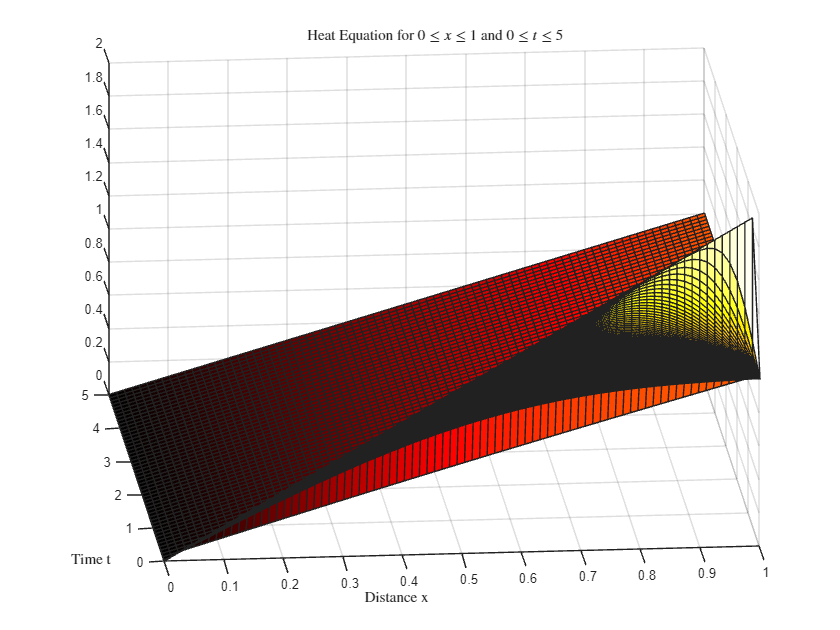

sol = pdepe(m,@heatpde,@heatIC,@heatBC,xMesh,tMesh);
colormap hot

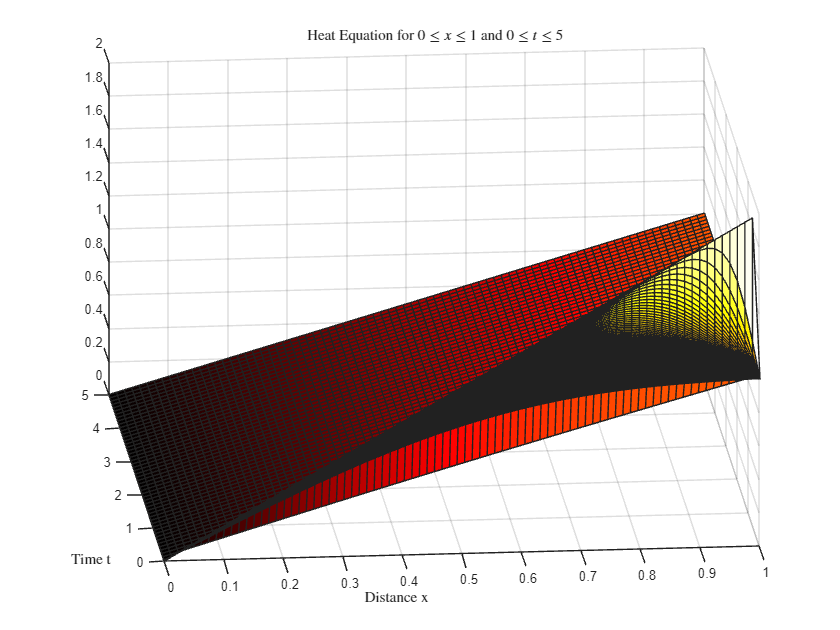

% imagesc(xMesh,tMesh,sol)
%colorbar
surf(xMesh,tMesh,sol)
xlabel('Distance x','interpreter','latex')
ylabel('Time t','interpreter','latex')
title('Heat Equation for $0 \le x \le 1$ and $0 \le t \le 5$','interpreter','latex')
view([-5.32 26.73])

p = plot(xMesh,heatIC(xMesh));
title("Solving the heat equation at $t = 0$", "Interpreter","latex")
subtitle("$\Delta t = $"+(tMesh(2)-tMesh(1)),"Interpreter","latex")
ax = p.Parent;
hold on
for j = 1:length(tMesh)
    delete(ax.Children(1:end-1))
    plot(xMesh,sol(j,:),'k')
    pause(0.1)
    drawnow
    title("Solving the heat equation at $t = $"+round(tMesh(j),3))
    if j == length(smtSteps)+1
        subtitle("$\Delta t = $" + (lrgtSteps(2)-lrgtSteps(1)))
    end
end
hold off

### Further Explorations: solving systems of PDEs

Just as it is possible to extend first-order ODE solvers to handle solving systems of ODEs, it is possible to extend PDE solvers to handle systems of PDEs. 

[Modeling tumor-related angiogenesis](https://www.mathworks.com/help/matlab/math/solve-angio-pde-system.html)

## Further Explorations: Partial Differential Equations Toolbox

Another common approach to numerically solving differential equations, especially with complicated geometry, is to discretize the spatial domain using triangles and the method in function space. This finite element method takes more mathematical background to understand but is commonly used in applications. 

[Thermal Stress Analysis of Jet Engine Turbine Blade](https://www.mathworks.com/help/pde/ug/thermal-stress-analysis-of-jet-engine-turbine-blade.html)

This example presents working with complicated geometry loaded from a CAD design program while modeling heat transfer.

[Helmholtz Equation on Disk with Square Hole](https://www.mathworks.com/help/pde/ug/helmholtzs-equation-on-disk-with-a-square-hole.html)

This example solves a 2-D wave equation on a circle with an obstruction in the center.

[Deflection Analysis of Bracket](https://www.mathworks.com/help/pde/ug/deflection-analysis-of-bracket.html)

This example presents the computation of the deflection and stress of a simple mounted bracket with a localized downward force applied.

[⇦ Main Menu](matlab:open('MainMenu.mlx'))